clf;

data = readtable('time-series-19-covid-combined.csv');

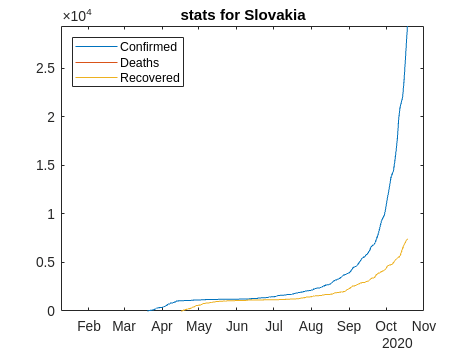

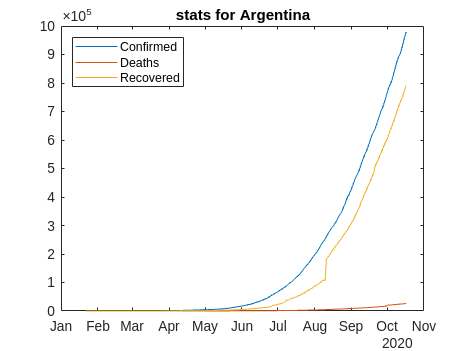

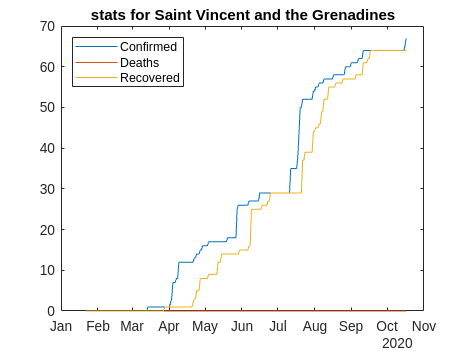

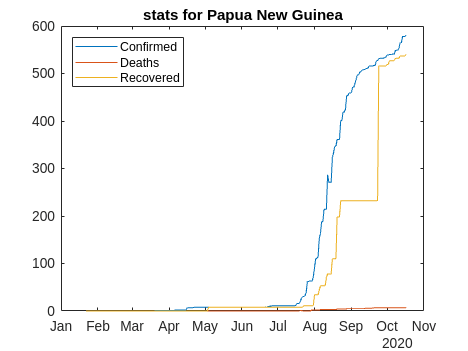

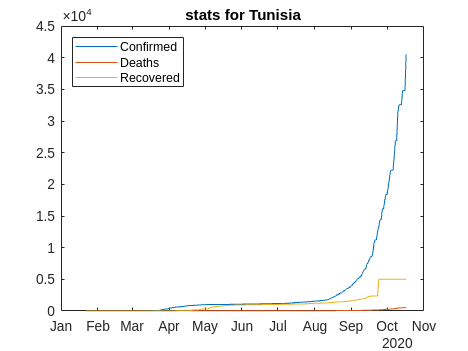

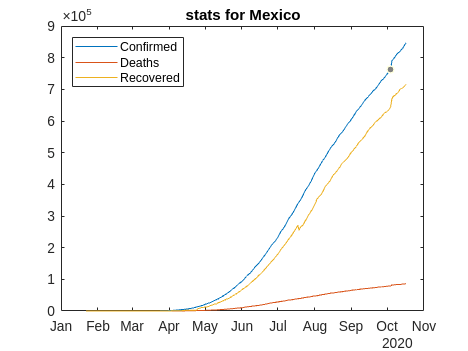

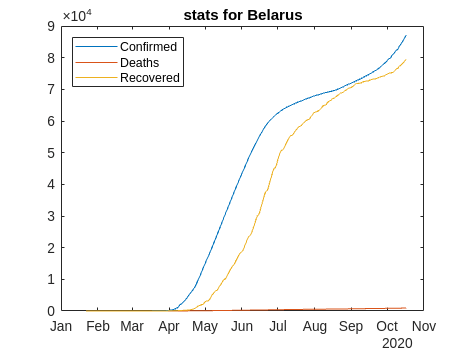

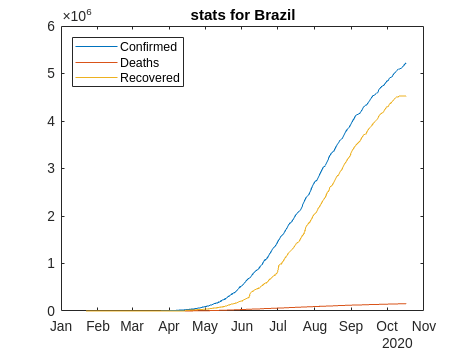


[C,ia] = unique(data.Country_Region);

for i=1:20
    
    N = randi([1,numel(C)],[1,20]);
    
    country = char(C(N(i)));
    T = data(strcmp(data.Country_Region, country),:);
    
    f = figure;
    plot(T.Date,[T.Confirmed,T.Deaths,T.Recovered]);
    title(['stats for ',country]);
    legend({'Confirmed','Deaths','Recovered'},'Location','northwest');

end